# PubChem_SDQ_Bibliometrics

Count references in PubChem, for example PubMed, Patent, Springer Nature, and Thieme Literature and bioactivity associated with a CID

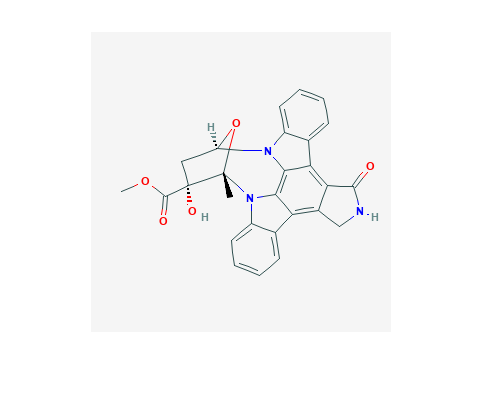

% Vincent F. Scalfani, Serena C. Ralph, Ali Al Alshaikh, and Jason E. Bara 
% The University of Alabama
% Version: 1.0, created with MATLAB R2018a

% N.B. PubChem SDQ query language is not officially supported from PubChem
% Results/syntax may change

% Define PubChem API
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
sdq = 'https://pubchem.ncbi.nlm.nih.gov/sdq/sdqagent.cgi?outfmt=json&query=';

% set MATLAB web options
options_api = weboptions('Timeout', 30);
options_sdq = weboptions('Timeout', 60, 'ContentType','json');

% Retrieve and display PNG Image of K-252a; CID = 3035817
CID_SS_query = '3035817';

CID_url = [api 'cid/' CID_SS_query '/PNG'];
[CID_img,map] = imread(CID_url);
imshow(CID_img,map)

## Perform a Similarity Search

% Search for chemical structures by Similarity Search (SS), 
% (2D Tanimoto threshold 99% to K-252a; CID = 3035817
api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
SS_url = [api 'fastsimilarity_2d/cid/' CID_SS_query '/cids/JSON?Threshold=99'];
SS_CIDs = webread(SS_url,options_api);
SS_CIDs = num2cell(SS_CIDs.IdentifierList.CID)

SS_CIDs = 58×1 cell array
    {[  3035817]}
    {[   490561]}
    {[     3813]}
    {[  9981346]}
    {[     3844]}
    {[ 16219545]}
    {[  9912412]}
    {[  9850141]}
    {[   454202]}
    {[ 11612445]}
    {[  9846716]}
    {[   127357]}
    {[134694132]}
    {[102446520]}
    {[ 98053103]}
    {[ 91050674]}
    {[ 90479780]}
    {[  9912410]}
    {[     3814]}
    {[101713437]}
    {[ 98053120]}
    {[ 71684641]}
    {[  9981344]}
    {[118593072]}
    {[ 91325395]}
    {[ 89474445]}
    {[ 89292811]}
    {[ 68771111]}
    {[ 59859198]}
    {[ 59502255]}
    {[ 59102941]}
    {[  9912413]}
    {[  6610352]}
    {[  6610264]}
    {[129090203]}
    {[ 44450630]}
    {[ 24867866]}
    {[ 16760062]}
    {[ 10814623]}
    {[  9890741]}
    {[ 10075889]}
    {[ 10672407]}
    {[ 10743375]}
    {[ 10743829]}
    {[ 25063037]}
    {[ 49868185]}
    {[ 51049453]}
    {[ 91885937]}
    {[ 98043294]}
    {[ 98118654]}
    {[101713435]}
    {[101726258]}
    {[102372026]}
    {[102372027]}
  

% set a CID limit to 100 max (can be higher, but useful for initial testing)
number_SS_CIDs = length(SS_CIDs)

number_SS_CIDs = 58

if number_SS_CIDs > 100
        
        SS_CIDs = SS_CIDs(1:100)      
else
    disp('Number of SS_CIDs not changed')    
end

Number of SS_CIDs not changed


## Retrieve Isomeric SMILES for CIDs, Number of Substances, Literature, Assay, and Bioactivity

for j = 1:length(SS_CIDs)
    CID = SS_CIDs{j};
    
    % define api call
    api = 'https://pubchem.ncbi.nlm.nih.gov/rest/pug/compound/';
    CID_IsoSMI_url = [api 'cid/' num2str(CID) '/property/IsomericSMILES/TXT'];
    
    % retrieve isomeric SMILES
    try
        CID_IsoSMI = webread(CID_IsoSMI_url,options_api);     
    catch ME  
        CID_IsoSMI = 'not found'
    end
        n = 0.5;
        pause(n)
            
    % add property data to SS_CIDs data array 
        SS_CIDs{j,2} = CID_IsoSMI;
    
    % define sdq call
    sdq = 'https://pubchem.ncbi.nlm.nih.gov/sdq/sdqagent.cgi?outfmt=json&query=';
    litCountQ_url = [sdq '{"hide":"*","collection":"*","where":{"ands":{"cid":"' num2str(CID) '"}}}'];
    
    try
        litCountQ = webread(litCountQ_url, options_sdq);
    catch ME
        litCountQ = 'not found'
    end
        n = 1;
        pause(n)
        
    % add count data to SS_CIDs data array
        
        % substance
        SS_CIDs{j,3} = litCountQ.SDQOutputSet(2).totalCount;
        
        % patent
        SS_CIDs{j,4} = litCountQ.SDQOutputSet(4).totalCount;
        
        % pubmed
        SS_CIDs{j,5} = litCountQ.SDQOutputSet(6).totalCount;
              
        % thiemechemistry
        SS_CIDs{j,6} = litCountQ.SDQOutputSet(12).totalCount;
        
        % springernature
        SS_CIDs{j,7} = litCountQ.SDQOutputSet(13).totalCount;
        
        % assay
        SS_CIDs{j,8} = litCountQ.SDQOutputSet(3).totalCount;
        
        % bioactivity
        SS_CIDs{j,9} = litCountQ.SDQOutputSet(44).totalCount;
                
end


## Compile Bibliometric Data into a Table

% convert cell array to string and remove leading and trailing white space
SS_CIDs_string = strtrim(string(SS_CIDs));

% convert to table
SSq_bibtable = array2table(SS_CIDs_string, 'VariableNames',{'CID','IsoSMI','substanes',...
    'patent','pubmed', 'thiemechemistry','springernature','assay','bioactivity'})

SSq_bibtable = 58×9 table
        CID                                                  IsoSMI                                               substanes    patent    pubmed    thiemechemistry    springernature    assay    bioactivity
    ___________    ___________________________________________________________________________________________    _________    ______    ______    _______________    ______________    _____    ___________

    "3035817"      "C[C@@]12[C@](C[C@@H](O1)N3C4=CC=CC=C4C5=C6C(=C7C8=CC=CC=C8N2C7=C53)CNC6=O)(C(=O)OC)O"           "42"        "17"     "696"           "0"              "645"         "504"       "623"   
    "490561"       "C[C@]12[C@@](C[C@H](O1)N3C4=CC=C

% data export as tabbed text file
% prompt user to select folder for data export
save_folder = uigetdir;
% change directory to selected folder
cd(save_folder)
writetable(SSq_bibtable,'MATLAB_Bibliometricsq_results.txt','Delimiter','tab')